Running Simulation For True Values

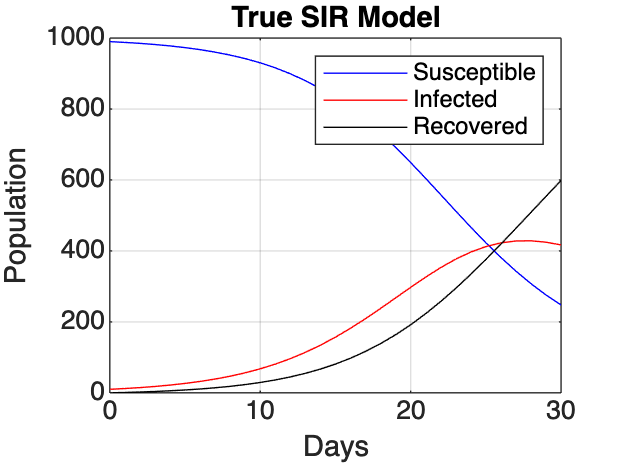

h = 1; % day
% Initial conditions
S0 = 990; 
I0 = 10;
R0 = 0; 

a = 0; % day 0 
b = 30; % day 100 (time simulation)
n = (b-a)/h; % step size
B = 0.3; % transmission rate
g = 0.1; % recovery rate for COVID
N = S0 + R0 + I0; % total population (constant)
t = linspace(a,b,n+1);
S = zeros(1,n+1);
I = zeros(1,n+1);
R = zeros(1,n+1);
S(1) = S0;
I(1) = I0;
R(1) = R0;

% Equations
fS = @(S,I) -B*S*I / N; % Susceptible function
fI = @(S,I) B*S*I / N - g*I; % Infected function
fR = @(I) g*I; % Recovered function 

% Fourth order Runge-Kutta method
for i = 1:n
    K1S = fS(S(i),I(i));
    K2S = fS(S(i)+0.5*h, I(i)+0.5*K1S*h);
    K3S = fS(S(i)+0.5*h,I(i)+0.5*K2S*h);
    K4S = fS(S(i+1),I(i)+K3S*h);
    S(i+1) = S(i) + (K1S+2*K2S+2*K3S+K4S)*(h/6);

    K1I = fI(S(i),I(i));
    K2I = fI(S(i) + 0.5*h, I(i) + 0.5*K1I*h);
    K3I = fI(S(i) + 0.5*h, I(i) + 0.5*K2I*h);
    K4I = fI(S(i+1), I(i) + K3I*h);
    I(i+1) = I(i) + (K1I+2*K2I+2*K3I+K4I)* (h/6);

    K1R = fR(I(i));
    K2R = fR(I(i) + 0.5*K1R*h);
    K3R = fR(I(i) + 0.5*K2R*h);
    K4R = fR(I(i) + K3R*h);
    R(i+1) = R(i) + (K1R+2*K2R+2*K3R+K4R)*(h/6);
end
plot(t,S,'b-')
grid on
hold on 
plot(t,I,'r-')
plot(t,R,'k-')
legend('Susceptible','Infected','Recovered','Location','Northeast')
title 'True SIR Model'
xlabel('Days')
ylabel('Population')
hold off

Least Squares Model

%% 30 Day Prediction
% Defining Variables
t1 = 0:1:30; n30 = length(t1); ktrue = (B*S0/N)-g;

% Calculating kpredict30
% Variable Substitution
v = log(I); k = t1;
a1 = (n30*sum(v.*k)-sum(v)*sum(k))/(n30*sum(k.^2)-(sum(k)^2));
kpredict30 = a1

kpredict30 =    0.132772254065627



% Calculating I0predict30
a0 = mean(v)-a1*mean(k);
I0predict30 = exp(a0)

I0predict30 =   15.542070892726882




% 10 Day Prediction
% Defining Variables
t2 = 0:1:10; n10 = length(t2);

% Calculating kpredict10
% Variable Substitution
V = log(I(1:length(t2))); K = t2;
a1 = (n10*sum(V.*K)-sum(V)*sum(K))/(n10*sum(K.^2)-(sum(K)^2));
kpredict10 = a1

kpredict10 =    0.191688968569561



% Calculating I0predict10
a0 = mean(V)-a1*mean(K);
I0predict10 = exp(a0)

I0predict10 =   10.103098435930715


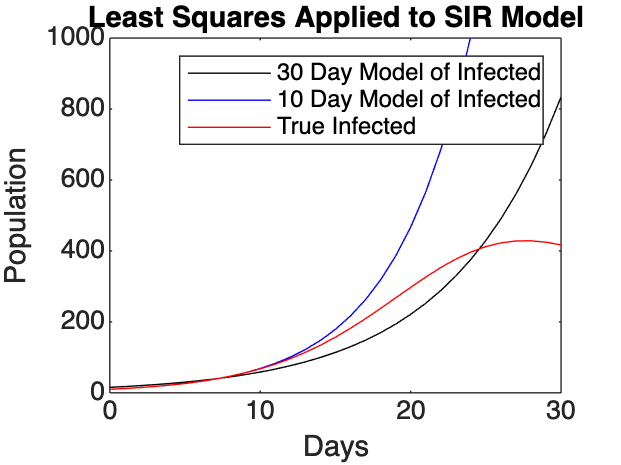


% Plotting Results (Sanity Check)
Ipredict30 = I0predict30*exp(kpredict30*t1);
Ipredict10 = I0predict10*exp(kpredict10*t1);

plot(t1,Ipredict30,'k-',t1,Ipredict10,'b-',t,I,'r')
xlim([0 30]), ylim([0 1000])
legend('30 Day Model of Infected','10 Day Model of Infected','True Infected','Location','Northeast')
title 'Least Squares Applied to SIR Model'
xlabel('Days')
ylabel('Population')

Discussion of Results

% Percent Difference From True Results
function y = PercentError(a,b)
    y = abs((a-b)/b) * 100;
end

PercentError(kpredict30,ktrue)

ans =   32.602916717956084


PercentError(I0predict30,I0)

ans =   55.420708927268812


PercentError(kpredict10,ktrue)

ans =    2.695955040832099


PercentError(I0predict10,I0)

ans =    1.030984359307148


As seen in the calculated percent differences, the estimates for k and the initial infected population are significantly more accurate using data for only the first 10 days of infections as opposed to data from the full 30 days. This is likely due to the fact that the the susceptible population (S) is constant. However, this is only an accurate assumpton early in the pandemic which is why the least squares models diverge from the true solution.